## The hacker parole problem

100 hackers have been imprisoned, but have been given a way to get parole.

Each of the 100 prisoners has been given a number.  There is also a room with 100 numbered boxes.  Each box contains a number.  Each prisoner goes into the room and has 50 tries to find their number in a box.

If all 100 prisoners can find their number within 50 tries, then they all get parole.  But, if one prisoner cannot find their number within 50 tries all the hackers go back to prison for another year.

The hackers meet and devise an algorithm that has better than a 30 percent chance of going free that year.

## The hacker's solution

It is obvious that having each prisoner randomly open boxes will fail.  Each prisoner has a 0.5 chance of finding their number and so the chance that all 100 are able to do it is 0.5^100.  Essentially giving a 0 probablility.

The hacker solution is to have each prisoner go into the room and use their number to find a box.  They open the box, and if their number is in it they are done.  If their number is not in it, then they use the number in the box to choose another box.  They continue following the numbers and opening boxes until they find the box with their number on it.

This solution will free all the prisoners over 30% of the time.  This is because the random numbers in boxes form loops.  For example if we have five boxes and five number we might see this set of numbers stored in boxes. Let's say that hacker #3 starts the search

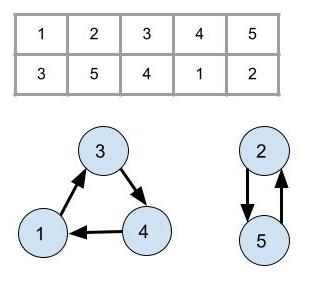

The following hackers would have the experience outlined by the loops:

- Opens box 1 and finds a 3. The 3 contains a 4. The 4 contains a 1. Done in 3

- Opens box 2 and finds a 5. The 5 contains a 2. Done in 2

- Opens box 3 and finds a 4. The 4 contains a 1. The 1 contains a 3. Done in 3

- Opens box 4 and finds a 1. The 1 contains a 3. The 3 contains a 4. Done in 3

- Opens box 5 and finds a 2.  The 2 contains a 5.  Done in 2.

Notice that hackers will always have to open all the boxes in the loop before they find their box.  That means that they will only get their freedom if the longest loop is the same length as the number of guesses they are given.  If the hackers in this example get 3 guesses, they go free.  If they get 2 guesses the go back to hacker jail.

### The 100 box problem

The hackers in this problem have 100 boxes and 50 guesses.  They will get their freedom if the longest loop contains 50 nodes or fewer. It turns out that 100 boxes will have a loop of 50 nodes or fewer 31% of the time. (Because of math not shown here.)

## Testing your `runTrial()` function

We want to test the hacker's algorithm by running 10,000 trials and seeing how often the hackers won their freedom.  Math says that in 10000 tries the hackers should go free between 3000 and 3500 times.

Your assignment is to write a function named **runTrial()** that takes a vector of boxes and runs one trial of the hacker's algorithm. runtrial() returns True if all the hackers find their box in 1/2 of the number of boxes or fewer. 

## The testing code

The test code runs your `runTrial()` function 10000 times and capture the number of times the hackers won their freedom. That number should be between 3000 and 3500.

## The hacker parole problem

100 hackers have been imprisoned, but have been given a way to get parole.

Each of the 100 prisoners has been given a number.  There is also a room with 100 numbered boxes.  Each box contains a number.  Each prisoner goes into the room and has 50 tries to find their number in a box.

If all 100 prisoners can find their number within 50 tries, then they all get parole.  But, if one prisoner cannot find their number within 50 tries all the hackers go back to prison for another year.

The hackers meet and devise an algorithm that has better than a 30 percent chance of going free that year.

### The hacker's solution

It is obvious that having each prisoner randomly open boxes will fail.  Each prisoner has a 0.5 chance of finding their number and so the chance that all 100 are able to do it is 0.5^100.  Essentially giving a 0 probablility.

The hacker solution is to have each prisoner go into the room and use their number to find a box.  They open the box, and if their number is in it they are done.  If their number is not in it, then they use the number in the box to choose another box.  They continue following the numbers and opening boxes until they find the box with their number on it.

This solution will free all the prisoners over 30% of the time.  This is because the random numbers in boxes form loops.  For example if we have five boxes and five number we might see this set of numbers stored in boxes.


$$\left(\begin{array}{cccccc} 1 & 2 & 3 & 4 & 5\\ 3 & 5 & 4 & 1 & 2 \end{array}\right)'$$


The hacker holding number 3 would open box 3 and find a 4.  Then the hacker would open box 4 and find a 1.  Then the hacker would open box 1 and find a 3. 

This solution works because numbers stored this way always form at least one loop.  In this case we have the following loops:

3 -> 4 -> 1 -> 3

5 -> 2 -> 5

The hackers know that they will get their freedom if the longest loop among the 100 boxes is 50 boxes or shorter.  This happens 30% of the time, thus they get their freedom 30% of the time.

## Testing the hacker's solution

We want to test the hacker's algorithm by running 10,000 trials and seeing how often the hackers won their freedom.  Math says that the number should be greater than or equal to 3000 times in 10,000 trials.

Your assignment is to write a function named `runTrial()` that takes a vector of boxes in the room and runs a trial of the hacker's algorithm. It returns whether the hackers found the number after looking at only half the boxes. The boxes are a vector that contains randomized numbers from 1:numBoxes.

The testbench will run your trial 10000 times and capture the number of times the hackers won their freedom. That number should be above 3000.

The test code looks like this:

First we set the parameters of our test.  We run 10000 trials with 100 boxes.

`numTrials = 10000;`

`numBoxes = 100;`

numTrials = 10000;
numBoxes = 100;

Now we create a logical vector that stores a 1 whenever a trial frees the hackers.

`tests = false([1,numTrials]);`

tests = false([1,numTrials]);

We now run the 10000 (`numTrials`) trials. We create a random set of boxes using `randperm()` and test the boxes using your `runTrial()` function.

`for ii=1:numTrials`

`   boxes = randperm(numBoxes);`

`   tests(ii) = runTrial(boxes);`

`end`

for ii=1:numTrials
   boxes = randperm(numBoxes);
   tests(ii) = runTrial(boxes);
end

## Checking your `runTrial()` Result

We've run a large number of trials.  The hackers should go free in 30-35% of the trials if we've implemented the algorithm properly.  

Here is the result:

disp(["Number of times the hackers went free: " nnz(tests)])

    "Number of times the hackers went free: "    "3216"



if (nnz(tests) >= numTrials * .30 && nnz(tests) < numTrials * .35)
    disp(['PROVEN:', nnz(tests), "is greater than 30% of",numTrials,"and less than 35%"])
else
    disp(["NOT PROVEN:", nnz(tests), "is less than 30% of",numTrials,"or greater than 35%"])
end

    "PROVEN:"    "3216"    "is greater than 30% of"    "10000"    "and less than 35%"



## Write the `runTrial(boxes)` function

The `runTrial()` function takes an vector of numbers that represent the boxes.  Each box contains a number less than or equal to the total number of boxes and all boxes contain different numbers.  The function returns `hackersFree`, which means all the hackers have found their number. The function works like this:

- Define a function named `runTrial` that takes `boxes` as an argument and returns `hackersFree`.

- Define a variable to contains the numbers of boxes by calling `numel` on `boxes`.

function hackersFree = runTrial(boxes)
    numBoxes = numel(boxes);

The program will simulate all the hackers looking in a box simultaneously.  The boxesToCheck vector contains the numbers of the boxes each hacker will open.  Hacker #1 will look in `boxes(boxesToCheck(1))`, hacker #2 will look in `boxes(boxesToCheck(2))``,` etc. 

Since all the hackers will first search in the box with their number the first `boxesToCheck` vector is just the vector from `1:numBoxes`.

    boxesToCheck = 1:numBoxes;

We see the number stored in each box by indexing `boxes` using `boxesToCheck`.

- Set the logical array `found` to be true for all cases where `boxesToCheck` matches the number in `boxes` indexed by boxesToCheck

- Set the scalar logical variable `hackersFree` to be true when the number of non-zero entries in `found` equals the number of boxes.

- Checking that all the hackers find their number in their box on the first try counts as one attempt. Set `attemptCount` to 1.

    found = boxesToCheck == boxes(boxesToCheck);
    hackersFree = nnz(found) == numBoxes;
    attemptCount = 1;

Now we loop until either `hackersFree` is true or we've attempted the search more than half the number of boxes.  

At the top of the loop we increment `attemptCount`.

    while ~hackersFree && (attemptCount <= numBoxes / 2)
        attemptCount = attemptCount + 1;

Now we update boxesToCheck based on our first search.  Some of the hackers must have been lucky and found their number.  We want to keep their number in `boxesToCheck` the same.  Hackers who didn't find their number should replace the number in `boxesToCheck` with the number in the box they checked.  

You can do this with a `for` loop and an `if` statement, or you can do something more clever in a single line using the fact that multiplying an array by a logical array produces a zero wherever the logical array had a zero.

        boxesToCheck=found .* boxesToCheck + ~found .* boxes(boxesToCheck);

Now check to see if the hackers found their numbers in the new boxes.  The statement `boxes(boxesToCheck)` will return the numbers `1:numBoxes` if all the `boxesToCheck` contain the same number as the box they check.

Store the result of your check in the `found` logical array.

        found = 1:numBoxes == boxes(boxesToCheck);

We've found all the boxes if the number of 1's in `found` is the same as the number of boxes.  The hackers go free if all of found is true.

        hackersFree = all(found);
    end
end
